## Problem 1 : Calculation of the Maximum Likelihood Estimation parameter a_hat

stestvector = reshape(sampletest, 784, 1);
strainvector = reshape(sampletrain, 784, 1);

stestvector = double(stestvector);
strainvector = double(strainvector);

%% Finding a_hat using ML estimation. 

a_hat = pinv(strainvector'*strainvector)*strainvector'*stestvector;

vectortrain = reshape(imageTrain, 784, 5000);
vectortestnew = reshape(imageTestNew, 784, 500);

vectortrain = double(vectortrain);
vectortestnew = double(vectortestnew);

x_new = a_hat * vectortrain;

disp(a_hat) %% This is the value of a_hat - ML estimation of a 

    0.6796



## Problem 2 : Classifying using the Least Squares distance metric


% For Problem 2 : Performing the task of classification using the 
% least square distance metric. 

closestmatch = zeros(1,500);

for i = 1:1:500
    mindistance = 5000;
        for j = 1:1:5000

            %euclidistance = norm(vectortestnew(:,i) - x_new(:,j));
            % Calculating the distance between these vectors from scratch
            % without using the canned function "norm" as shown above.

             euclidistance = sqrt(sum((vectortestnew(:,i) - x_new(:,j)) .^2));
                if euclidistance < mindistance

                    mindistance = euclidistance;
                    closestmatch(i) = j;
                end
        end
end

% Calculating the total errors for Problem 2
errorsfor2 = zeros(1,10);

for k = 1:1:500

    Traininglabel = labelTrain(closestmatch(k));

    Testinglabel = labelTestNew(k);

    if Traininglabel ~= Testinglabel
        errorsfor2(1, Testinglabel + 1) = errorsfor2(1, Testinglabel + 1) + 1;
    end
end

errorsperclass2 = zeros(10,1);
classesfor2 = zeros(10,1);


%% Error rate per class for least squares distance metric

classsumv = zeros(1,10);
for t = 0:1:9
    class_t = labelTestNew == t;
    classsumv(t+1) = sum(class_t);
end

for h = 0:1:9
    errorsperclass2(h+1) = errorsfor2(h+1)/classsumv(h+1);
end


total = sum(errorsfor2);
totalerrorrate2leastsquares = total/500;
disp(totalerrorrate2leastsquares) % Error rate for problem 2

    0.1120




points = 0:1:9

points =      0     1     2     3     4     5     6     7     8     9


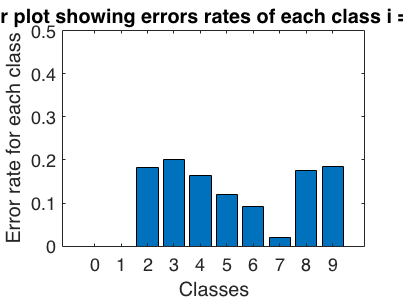


figure(2)
bar(points, errorsperclass2)
xlabel('Classes');
ylabel('Error rate for each class');
title('Bar plot showing errors rates of each class i = 0...9');
ylim([0 0.5]);

## Problem 3 : Classifying using the Euclidean distance metric


% For Problem 3 : Performing the task of classification using the Euclidean
% distance metric. 
closestmatch1 = zeros(1,500);

for l = 1:1:500
    mindistance1 = 5000;
        for p = 1:1:5000
            % euclidistance1 = norm(vectortestnew(:,l) - vectortrain(:,p));
              euclidistance1 = sqrt(sum((vectortestnew(:,l) - vectortrain(:,p)) .^2));
                if euclidistance1 < mindistance1

                    mindistance1 = euclidistance1;
                    closestmatch1(l) = p;
                end
        end
end


% Calculating the total errors as well as the error rate per class 
errorsfor3 = zeros(1,10);

for m = 1:1:500

    Traininglabel = labelTrain(closestmatch1(m));

    Testinglabel = labelTestNew(m);

    if Traininglabel ~= Testinglabel
        errorsfor3(1, Testinglabel + 1) = errorsfor3(1, Testinglabel + 1) + 1;
    end
end

%% Error rate per class for euclidean distance metric
errorsperclass3 = zeros(10,1);

for e = 0:1:9
    errorsperclass3(e+1) = errorsfor3(e+1)/classsumv(e+1);
end


total1 = sum(errorsfor3);
totalerrorrate3euclidean = total1/500;

disp(totalerrorrate3euclidean) % Error rate for problem 3

    0.2120



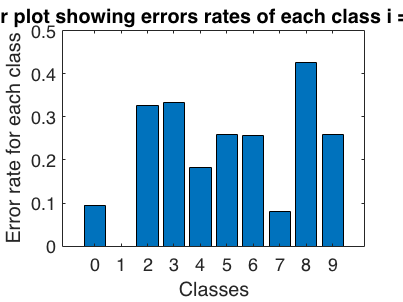



figure(3)
bar(points,errorsperclass3)
xlabel('Classes');
ylabel('Error rate for each class');
title('Bar plot showing errors rates of each class i = 0...9');
ylim([0 0.5]);


%% As seen here, the error rates per class as well as the overall error rate
%% when using the least squares distance metric is much better than using the
%% euclidean distance metric. The least squares distance metric provides a 
%% 10% improvement in overall classification over the euclidean distance metric